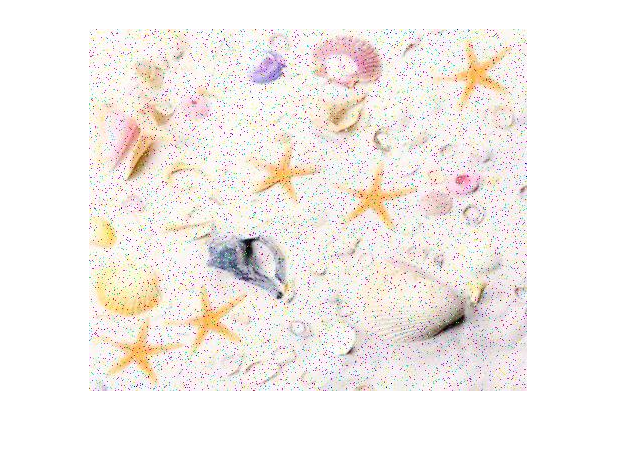

% Step 1 Read in an image

% orig = original image that is going to be passed through the pipeline
orig = imread('starfish.jpg');
star = orig;
imshow(orig);


% Checking the image data that gets stored in the workspace
whos orig;

  Name        Size                Bytes  Class    Attributes

  orig      362x438x3            475668  uint8              



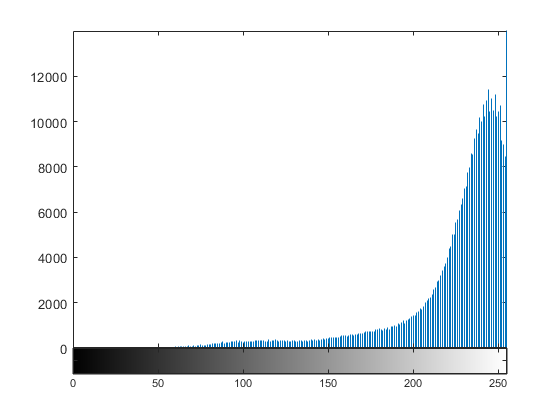


% Seeing what the image contrast is like to ensure that the full range is
% used. Equalising spreads the intensity values over the full range of the image.
figure
imhist(star);

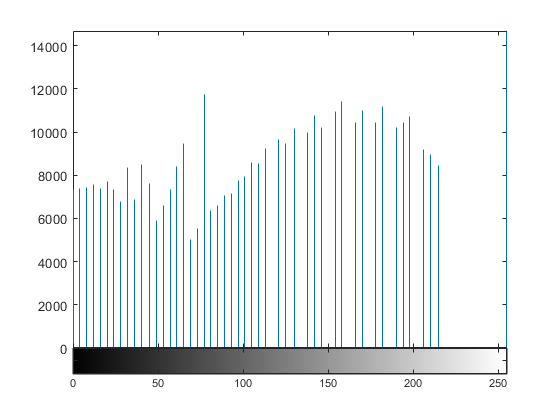


equalized = histeq(star);

figure
imhist(equalized);

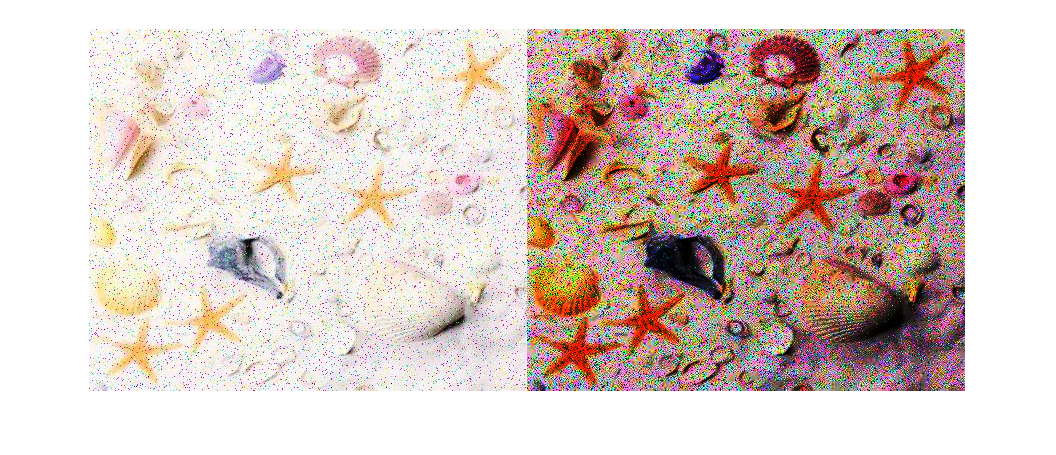


figure
imshowpair(star,equalized,'montage');

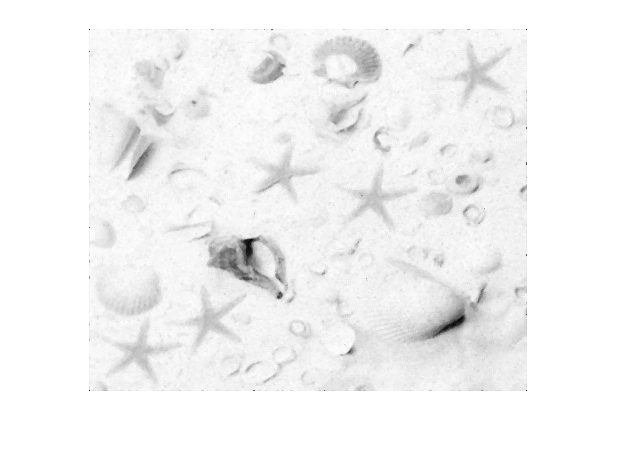


% Step 2 Process the image
star = filterImage(star);

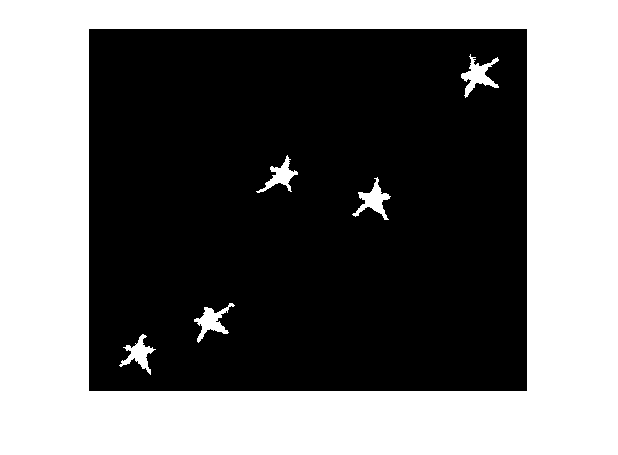

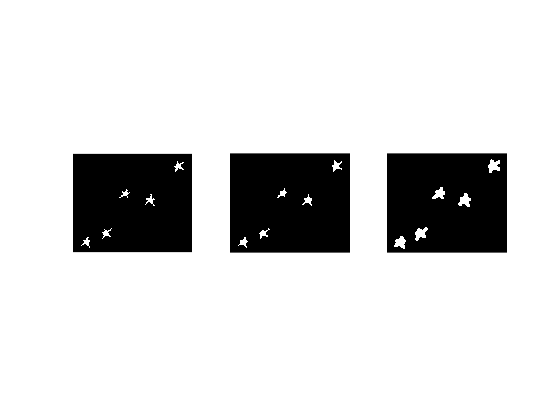

star = binaryObjectDetection(star,orig);

connected = "5"

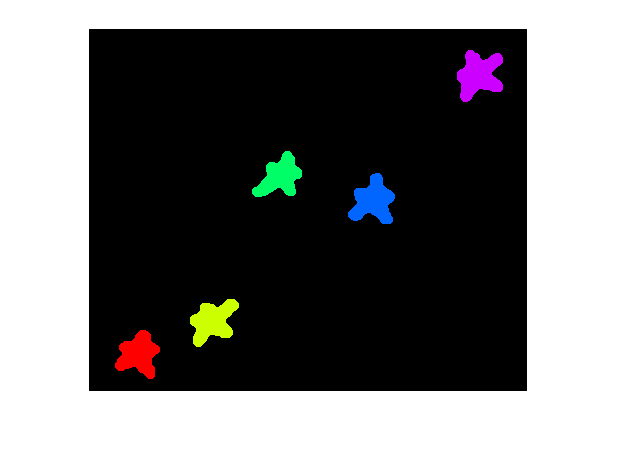

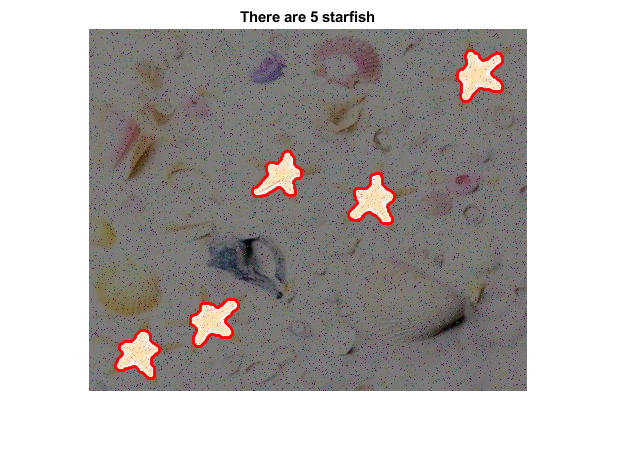

rgb = objectCount(star, orig);




% figure
% hold on;
% 
% subplot(2,2,1);
% imshowpair(star, edge(rgb2gray(star), 'Canny'), 'montage');
% subplot(2,2,2);
% imshowpair(star, edge(rgb2gray(star), 'Canny'), 'montage');
% 
% hold off; 

% Step 2.1 filter the image

function star = filterImage(star)
    star = rgb2gray(star);
    star = medfilt2(star);
    imshow(star);
end


% Step 2.2 Threshold the image
function star = binaryObjectDetection(star,orig)
    thresh = graythresh(star);
    imshowpair(orig,star,'montage');
    
    % Step 2.3 Binarize the image
    
    mask = imbinarize(star,thresh);
    imshowpair(star,mask,'montage');

    % Step 2.4 Bring the image to the forefront
    
    star = imcomplement(mask);
    imshowpair(orig,star,'blend');
    
    % Step 2.5 Clean up the mask so that detecting the object is easier
    mask2 = bwareaopen(star, 350);
    
    %Using an xor so that the larger ojects such as the shells will be removed
    mask3 = xor(bwareaopen(star, 350), bwareaopen(star,630));
    imshowpair(mask3,mask2,'montage');
    
    star = imfill(mask3,'holes');
    imshow(star);
    
    % Step 3
    close_se = strel('disk',8,4);
    dilate_se = strel('disk',5,4);
    closeBW = imclose(star,close_se);
    dilateBW = imdilate(closeBW,dilate_se);
    figure
    subplot(1,3,1);
    imshow(star);
    subplot(1,3,2);
    imshow(closeBW);
    subplot(1,3,3);
    imshow(dilateBW);
    
    star = dilateBW;

end


function rgb = objectCount(star, orig)

    [l, connected] = bwlabel(star,4);

    rgb = label2rgb(l,'hsv','k');
    
    connected = string(connected);
    
    connected
    
    figure
    imshow(rgb);
    
    objectHighlighting(rgb, star, connected, orig);
end

function objectHighlighting(rgb, star, connected, orig)
    info = regionprops(rgb,orig,'BoundingBox');
    numberOfBlobs = size(info, 1);
    
    figure
    subplot(1,1,1);
    imshowpair(orig,star,'blend');
    titlestr = append("There are ", connected, " starfish");
    title(titlestr);
    axis image;
    hold on;
    bounds = bwboundaries(star);
    numberOfBounds = size(bounds,1);
    for k = 1 : numberOfBounds
        thisBoundary = bounds{k};
        plot(thisBoundary(:,2), thisBoundary(:,1), 'r', 'LineWidth', 2);
    end
    hold off;
end


% displayPrewitt(orig);
% displayPrewitt(equalized);
% 
% saltAndPepper(orig);
% saltAndPepper(equalized);
% 
% displaySobelPrewitt(orig);
% displaySobelPrewitt(equalized);

% displayInFigure(orig);
% displayInFigure(equalized);

function displaySobelPrewitt(orig)

    gray = rgb2gray(orig);
    
    prewitt = edge(gray, 'Prewitt');
    sobel = edge(gray, 'Sobel');
    laplacian = edge(gray, 'log');

    figure
    hold on;

    subplot(3,1,1);
    imshowpair(prewitt,gray,'montage');
    title('Prewitt');
    subplot(3,1,2);
    imshowpair(sobel,gray,'montage');
    title('Sobel');
    subplot(3,1,3);
    imshowpair(laplacian,gray,'montage');
    title('Laplacian with Gaussian');

    hold off;

end

function displayPrewitt(orig)

    one = orig(:,:,1);
    two = orig(:,:,2);
    three = orig(:,:,3);
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    pone = edge(one, 'Prewitt');
    ptwo = edge(two, 'Prewitt');
    pthree = edge(three, 'Prewitt');
    
    figure
    hold on;

    subplot(3,1,1);
    imshowpair(pone,one,'montage');
    title('Prewitt');
    subplot(3,1,2);
    imshowpair(ptwo,two,'montage');
    title('Sobel');
    subplot(3,1,3);
    imshowpair(pthree,three,'montage');
    title('Laplacian with Gaussian');

    hold off;

end

function saltAndPepper(orig)

    % 1. channel split
    red = orig(:,:,1); % Redchannel
    green = orig(:,:,2); % Greenchannel
    blue = orig(:,:,3); % Bluechannel
    black = zeros(size(orig,1), size(orig,2), 'uint8');

    % 2. mean filter channels
    r = uint8(conv2(red,ones(3)/9));
    g = uint8(conv2(green,ones(3)/9));
    b = uint8(conv2(blue,ones(3)/9));

    % 3. mean channels recombined
    mean = cat(3, r, g, b);

    % 4. median filter channels
    rmed = uint8(medfilt2(red));
    gmed = uint8(medfilt2(green));
    bmed = uint8(medfilt2(blue));

    % 5. median channels recombined
    median = cat(3, rmed, gmed, bmed);
    
    figure
    hold on;
    
    subplot(1,3,1);
    imshow(orig);
    title('original');
    
    subplot(1,3,2);
    imshow(mean);
    title('mean');
    
    subplot(1,3,3);
    imshow(median);
    title('median');
    
    hold off;

end

function [one, two, three, onefilt, twofilt, threefilt, filtered] = filterWithKernel(orig, kernel, t)

    % 1. channel split
    one = orig(:,:,1); % Hue
    two = orig(:,:,2); % Saturation
    three = orig(:,:,3); % Value
    black = zeros(size(orig,1), size(orig,2), 'uint8');
    
    % 2. first derivative Convolution filter channels
    onefilt = uint8(conv2(one,kernel));
    twofilt = uint8(conv2(two,kernel));
    threefilt = uint8(conv2(three,kernel));
    
    % 3. channels recombined
    filtered = cat(3, onefilt, twofilt, threefilt);
    
    figure
    hold on;
    
    subplot(3,3,2)
    imshow(filtered);
    title(t);
    
    subplot(3,3,4);
    imshow(one);
    title('channel 1');
    subplot(3,3,5);
    imshow(two);
    title('channel 2');
    subplot(3,3,6);
    imshow(three);
    title('channel 3');
    
    subplot(3,3,7);
    imshow(onefilt);
    title('channel 1 filtered');
    subplot(3,3,8);
    imshow(twofilt);
    title('channel 2 filtered');
    subplot(3,3,9);
    imshow(threefilt);
    title('channel 3 filtered');
    
    hold off;

end

function greyFilter(orig, kernel, t)
    
    out = uint8(conv2(orig,kernel));
    
    figure
    hold on;
    
    imshowpair(orig,out,'montage');
    title(t);
    
    hold off;

end

function displayInFigure(orig)
    
    prewit_x_horizontal = [ -1 0 1; -1 0 1; -1 0 1 ];
    prewitX = 'prewitt x';
    prewit_y_vertical = [ -1 -1 -1; 0 0 0; 1 1 1 ];
    prewitY = 'prewitt y';

    sobel_x_horizontal = [ -1 0 1; -2 0 2; -1 0 1 ];
    sobelX = 'sobel x';
    sobel_y_vertical = [ -1 -2 -1; 0 0 0; 1 2 1 ];
    sobelY = 'sobel y';
    
    first_derivitave_x_pos = [0 0 0; -1 0 1; 0 0 0];
    firstDeriv = 'first derivative';

    laplaction_kernel = [ 0 1 0; 1 -4 1; 0 1 0 ]; 
    laplacion = 'laplacian';
    
    % step 1 get the images
    
    greyOrig = rgb2gray(orig);
    hsvOrig = rgb2hsv(orig);
    
    filterWithKernel(orig, prewit_x_horizontal, prewitX);
    filterWithKernel(orig, prewit_y_vertical, prewitY);
    filterWithKernel(orig, sobel_x_horizontal, sobelX);
    filterWithKernel(orig, sobel_y_vertical, sobelY);
    filterWithKernel(orig, first_derivitave_x_pos, firstDeriv);
    filterWithKernel(orig, laplaction_kernel, laplacion);
    
    greyFilter(greyOrig, prewit_x_horizontal, prewitX);
    greyFilter(greyOrig, prewit_y_vertical, prewitY);
    greyFilter(greyOrig, sobel_x_horizontal, sobelX);
    greyFilter(greyOrig, sobel_y_vertical, sobelY);
    greyFilter(greyOrig, first_derivitave_x_pos, firstDeriv);
    greyFilter(greyOrig, laplaction_kernel, laplacion);
    
    filterWithKernel(hsvOrig, prewit_x_horizontal, prewitX);
    filterWithKernel(hsvOrig, prewit_y_vertical, prewitY);
    filterWithKernel(hsvOrig, sobel_x_horizontal, sobelX);
    filterWithKernel(hsvOrig, sobel_y_vertical, sobelY);
    filterWithKernel(hsvOrig, first_derivitave_x_pos, firstDeriv);
    filterWithKernel(hsvOrig, laplaction_kernel, laplacion);
    
end